# Notes for Digital Audio Theory - A Practical Guide Chapter 8: FIR Filters

## Add dependencies and reset the environment

addpath('Functions'); addpath('AudioSamples'); clear;clc;close

## 8.1 FIR filters by way of example

A Finite Impulse Response Filter is a feed-forward structure with an impulse response that is a finite length. As this structure is feed-forward there is no delayed version of the ouput in the difference equation used to create feedback, only delayed versions of the input. The FIR Filter will have an impulse response whose length in samples corresponds to the highest number of taps, this is also called the order. 

An example FIR filter with the difference equation...


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +a_1 \cdot x\left\lbrack n-k\right\rbrack$$


x = [.1 .4 .5 .2]; y = FIRFilter(x, 1, .5); % Input; Output;

Expected results [0.1, 0.45, 0.7, 0.45, 0.1]

x2 = [.5 -.4 .3 -.2 .1]; y2 = FIRFilter(x2, 1, .5); % Input; Output;

Expected results [0.5, -0.15, 0.1, -0.05, 0.0, 0.05]

"More generally, the output of an FIR filter has a sequence length that is equal to the length of the input plus the order of the filter."

## Analysis

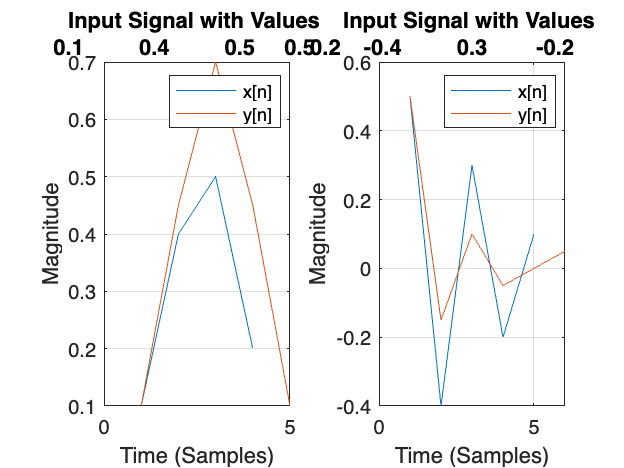

subplot(1, 2, 1); FIRPlot(x, y); subplot(1, 2, 2); FIRPlot(x2, y2);

## 8.2 Impulse response

The impulse response of a filter has a finite length of N+1. Where N is the order of the filter (in the case of our filters the order is 1), and 1 is the length of x[n]. The impulse response for the first order low pass filter from section 8.1 can be calculated as


$$y\left\lbrack n\right\rbrack =x\left\lbrack 0\right\rbrack +0\ldotp 5\cdot x\left\lbrack 0-1\right\rbrack =1\ldotp 0+0\ldotp 5\cdot 0\ldotp 0=1\ldotp 0$$


## 8.3 Convolution

## 8.4 Cross-correlation

## 8.5 FIR filter phase

## 8.6 Designing FIR filters

## 8.7 Challenges

## 8.8 Project – FIR filters